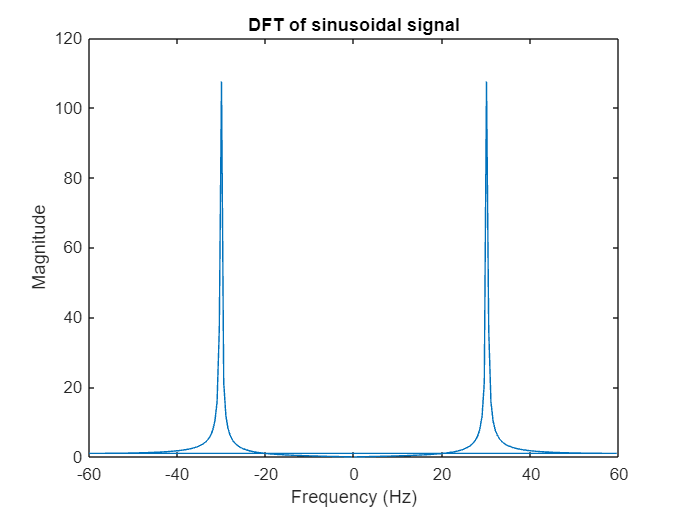

%QUESTION 1


% Define parameters
alpha = 1+mod(217,3); % You can change this value
f = 15 * alpha; % Frequency in Hz
T = 2; % Duration in seconds
fs = 120; % Sampling rate in samples/sec
N = fs * T; % Number of samples

% Generate the signal
t = linspace(0, T, N); % Time vector
x = sin(2 * pi * f * t); % Signal vector

% Compute the DFT
X = fft(x); % DFT vector
X_mag = abs(X); % Magnitude vector
freq = fftshift((-N/2:N/2-1) * fs / N); % Frequency vector

% Plot the DFT magnitude
plot(freq, X_mag)
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('DFT of sinusoidal signal')

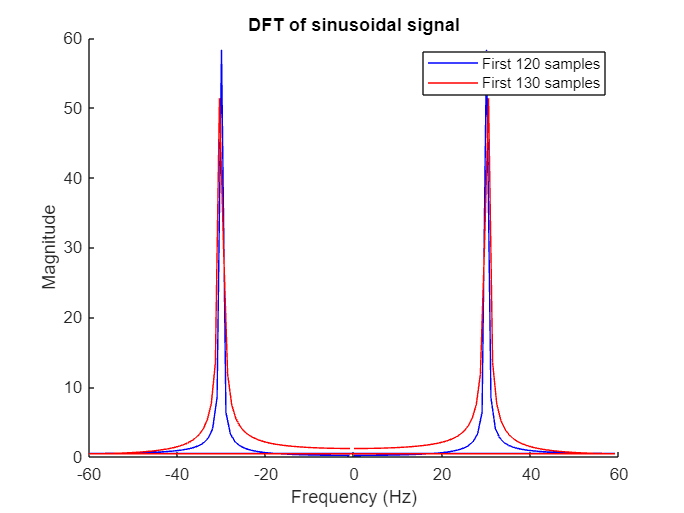





% Define parameters
alpha =1+mod(217,3); % You can change this value
f = 15 * alpha; % Frequency in Hz
T = 2; % Duration in seconds
fs = 120; % Sampling rate in samples/sec
N = fs * T; % Number of samples

% Generate the signal
t = linspace(0, T, N); % Time vector
x = sin(2 * pi * f * t); % Signal vector

% Compute the DFT of the first 120 samples
X1 = fft(x(1:120)); % DFT vector
X1_mag = abs(X1); % Magnitude vector
freq1 = fftshift((-120/2:120/2-1) * fs / 120); % Frequency vector

% Compute the DFT of the first 130 samples
X2 = fft(x(1:130)); % DFT vector
X2_mag = abs(X2); % Magnitude vector
freq2 = fftshift((-130/2:130/2-1) * fs / 130); % Frequency vector

% Plot the DFT magnitudes on the same figure
figure
hold on
plot(freq1, X1_mag, 'b')
plot(freq2, X2_mag, 'r')
hold off
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('DFT of sinusoidal signal')
legend('First 120 samples', 'First 130 samples')

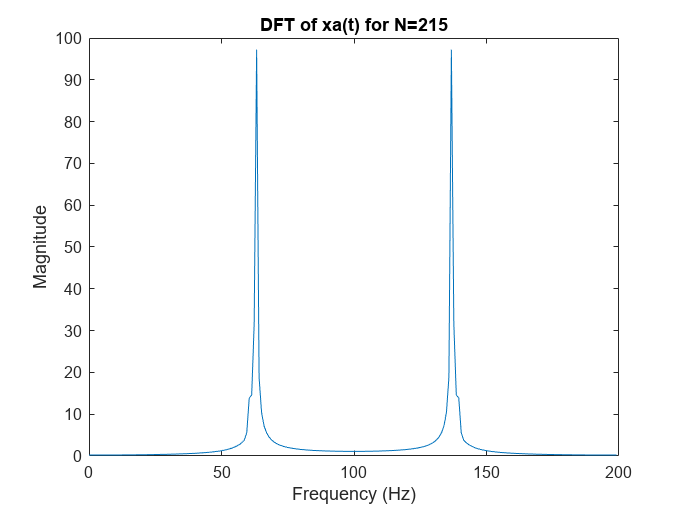

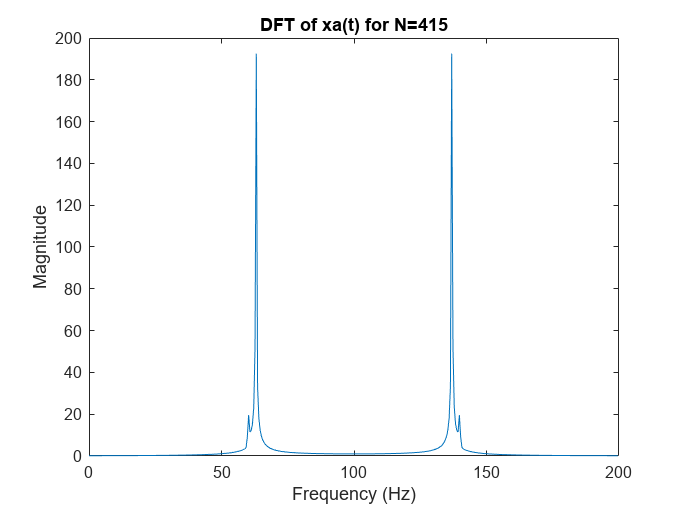

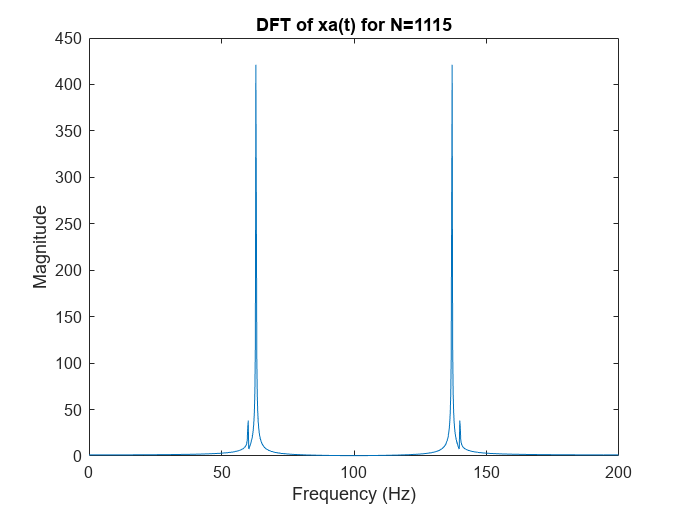

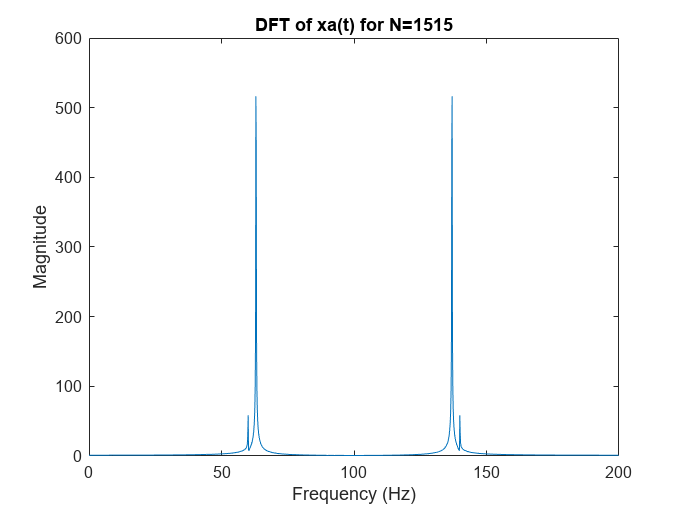

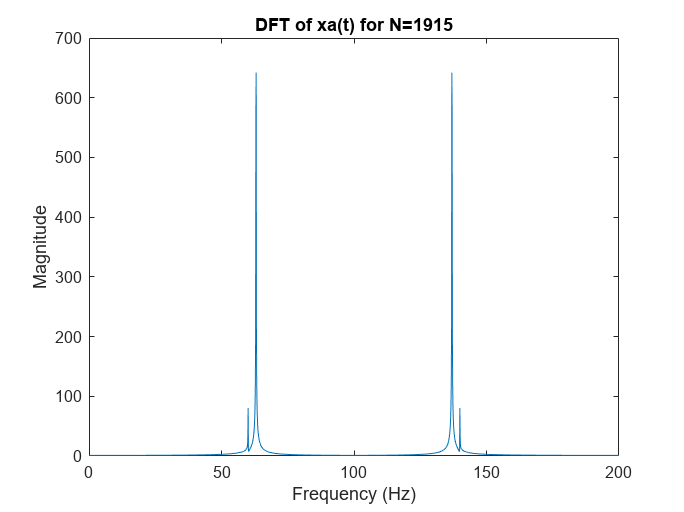








%QUESTION 2

% Define the signal parameters
alpha =1+mod(217,3); % You can change this value

A = [120, 140, 160];
B = [126, 146, 166];

% Define the time vector
t = linspace(0, 10, 2000);

% Generate the signal
xa = zeros(length(alpha), length(t));
for i = 1:length(alpha)
    xa(i,:) = 0.1*sin(A(i)*pi*t) + cos(B(i)*pi*t);
end

% Plot the DFT of the signal for different sample sizes
samples = [215, 415, 1115, 1515, 1915];
for i = 1:length(samples)
    N = samples(i);
    Xa = fft(xa(:,1:N), [], 2);
    f = (0:N-1)*(200/N);
    figure;
    plot(f, abs(Xa));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(sprintf('DFT of xa(t) for N=%d', N));
end

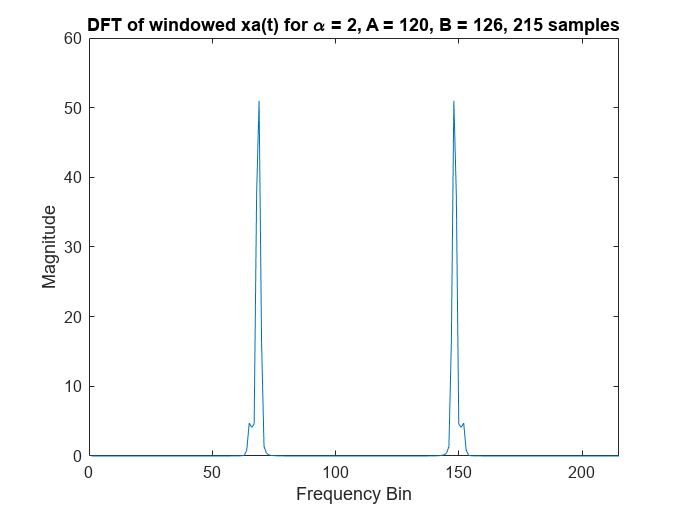

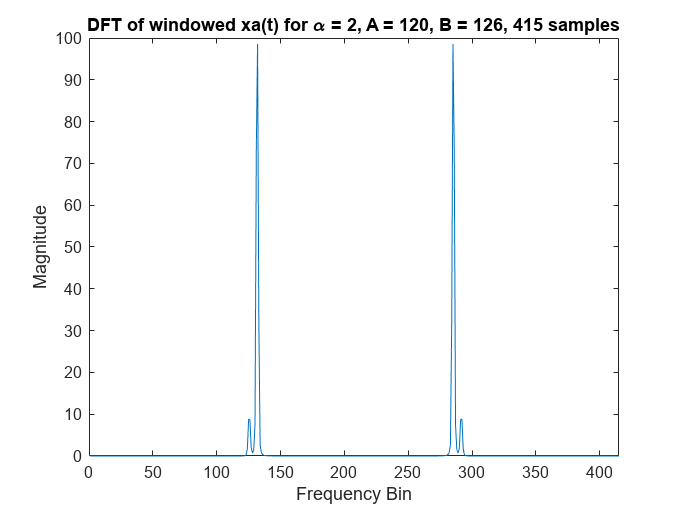

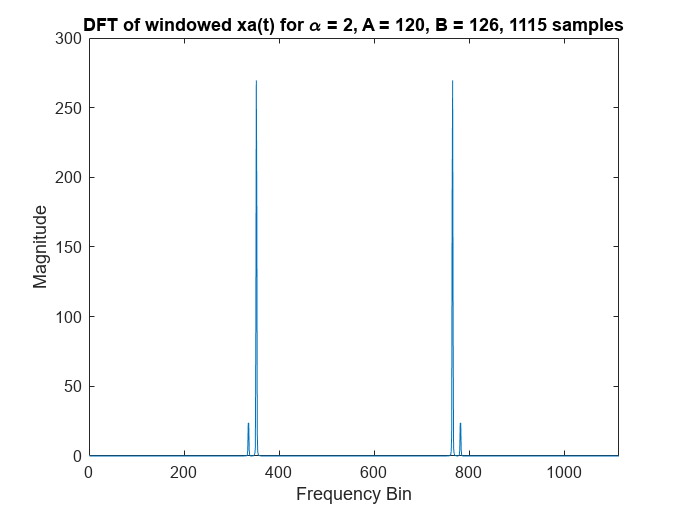

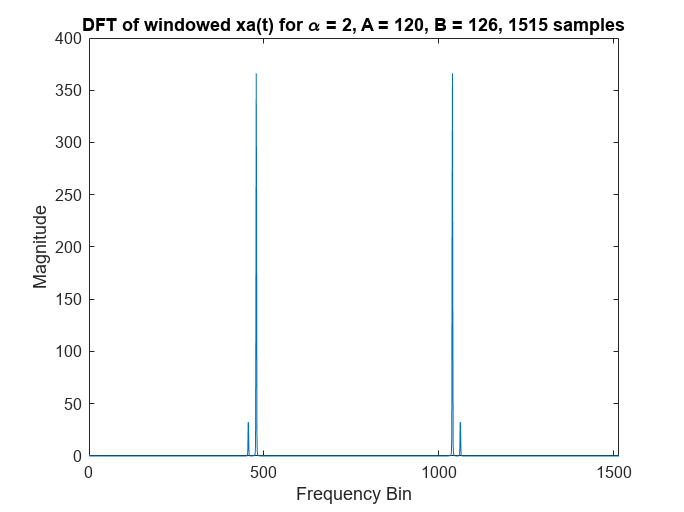

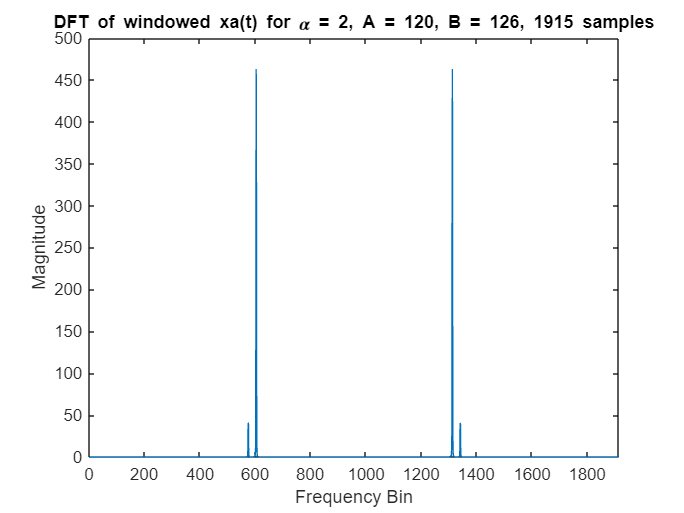





%QUESTION 3


% Constants
duration = 10;             % Duration in seconds
sampling_rate = 200;       % Sampling rate in samples/second
alpha_values = 1+mod(217,3);  % Alpha values
A_values = [120, 140, 160]; % A values
B_values = [126, 146, 166]; % B values

% Time vector
t = 0:1/sampling_rate:duration;
 for alpha_idx = 1:length(alpha_values)
    alpha = alpha_values(alpha_idx);
    A = A_values(alpha_idx);
    B = B_values(alpha_idx);
    
    % Generate signal xa(t)
    xa = 0.1 * sin(A * pi * t) + cos(B * pi * t);
    
    % Sample the signal
    sample_indices = [215, 415, 1115, 1515, 1915];
    for sample_idx = 1:length(sample_indices)
        num_samples = sample_indices(sample_idx);
        sampled_xa = xa(1:num_samples);
        
        % Apply window
        if alpha == 1
            window = hamming(num_samples);
        elseif alpha == 2
            window = hann(num_samples);
        elseif alpha == 3
            window = blackman(num_samples);
        else
            error('Invalid alpha value');
        end
        
        windowed_xa = sampled_xa .* window';
        
        % Compute the DFT
        X = fft(windowed_xa);
        
        % Plot the DFT
        figure;
        plot(abs(X));
        title(['DFT of windowed xa(t) for \alpha = ', num2str(alpha), ', A = ', num2str(A), ', B = ', num2str(B), ', ', num2str(num_samples), ' samples']);
        xlabel('Frequency Bin');
        ylabel('Magnitude');
        xlim([0, num_samples]);
    end
 end




%QUESTION 4

% Parameters
alpha  = 1 + mod(217,3)

alpha = 2

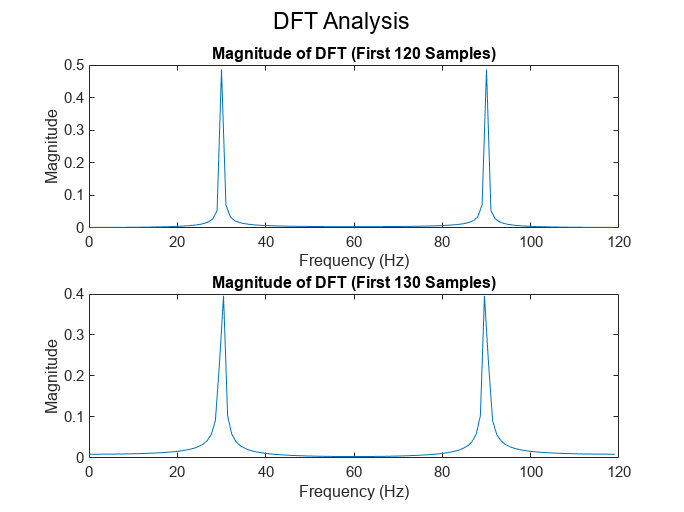

duration = 2;  % seconds
sampling_rate = 120;  % samples per second
frequency = 15 * alpha;  % α Hz
N = duration * sampling_rate;  % Total number of samples

% Generate the time vector
t = linspace(0, duration, N);

% Generate the unit amplitude sinusoidal signal
signal = sin(2 * pi * frequency * t);

% Calculate the Discrete Fourier Transform (DFT) of the first 120 samples
dft_120 = abs(fft(signal(1:120))/120);

% Calculate the Discrete Fourier Transform (DFT) of the first 130 samples
dft_130 = abs(fft(signal(1:130))/130);
% Frequency axis for plotting
freq_axis = 0:119;
freq_axis1 =(0:129)*120/130;

% Plot the magnitude of the DFT for the first 120 samples
subplot(2, 1, 1);
plot(freq_axis, dft_120);
title('Magnitude of DFT (First 120 Samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plot the magnitude of the DFT for the first 130 samples
subplot(2, 1, 2);
plot(freq_axis1, dft_130);
title('Magnitude of DFT (First 130 Samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Adjust the figure for better visualization
sgtitle('DFT Analysis');
set(gcf, 'Position', [100, 100, 800, 600]);

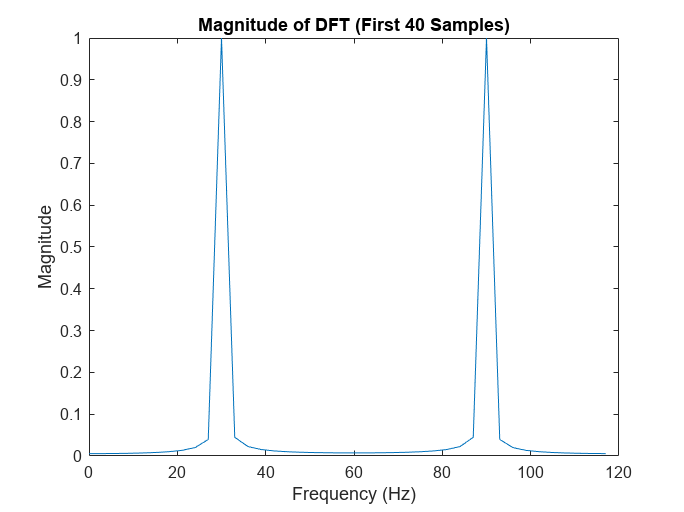


% Show the plots
figure;

dft_40 = abs(fft(signal(1:40))/max(fft(signal(1:40))));
freq_axis2 =(0:39)*120/40;
plot(freq_axis2, dft_40);
title('Magnitude of DFT (First 40 Samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

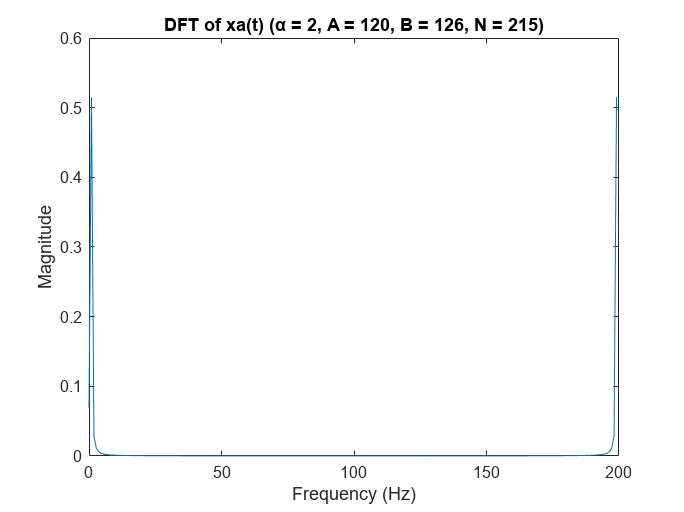

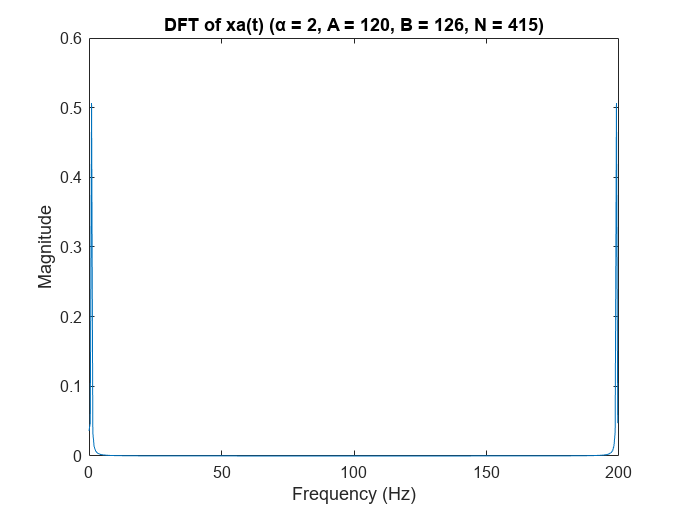

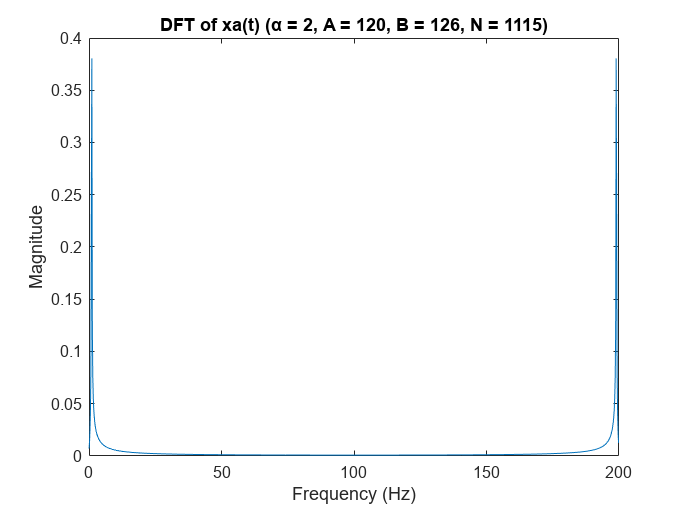

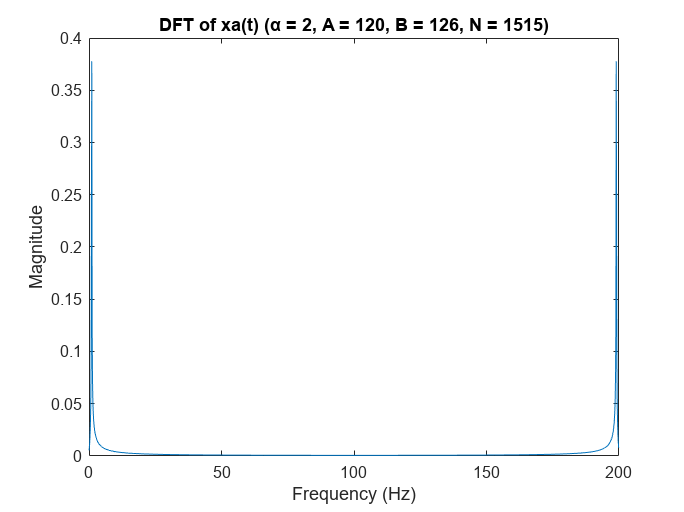

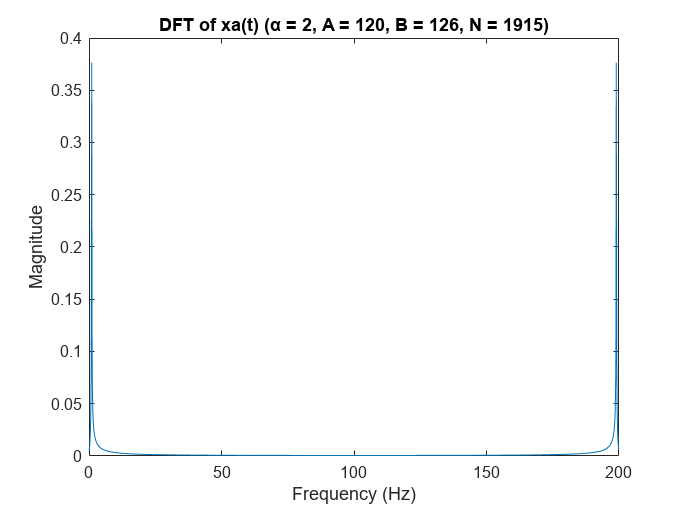


% Parameters
alpha_values =  1;
A_values = 100;
B_values = 126;
duration = 10;  % seconds

% Generate time vector
t = linspace(0, duration, duration * 200);
    
    % Generate the signal xa(t)
signal = 0.1 * sin(alpha * pi * t) + cos(alpha * pi * t);

    % Plot the DFT of the signal for different sample counts
sample_counts = [215, 415, 1115, 1515, 1915];    
for j = 1:length(sample_counts)    
    N = sample_counts(j);
    sample_signal = signal(1:N);   
        
        % Compute the DFT and the frequency axis
    dft = abs(fft(sample_signal)/N);
    freq_axis = (0:N-1)*200/N;   

        % Plot the DFT
    figure;   
    plot(freq_axis, dft);   
    title(sprintf('DFT of xa(t) (α = %d, A = %d, B = %d, N = %d)', alpha, A, B, N));   
    xlabel('Frequency (Hz)');   
    ylabel('Magnitude');   
end       

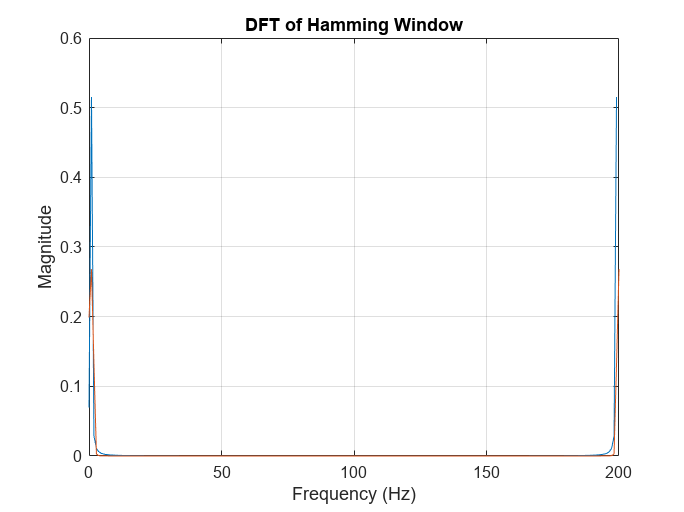

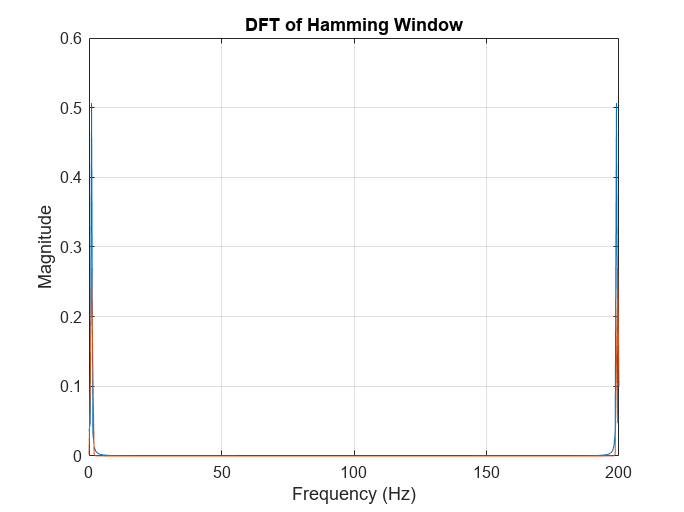

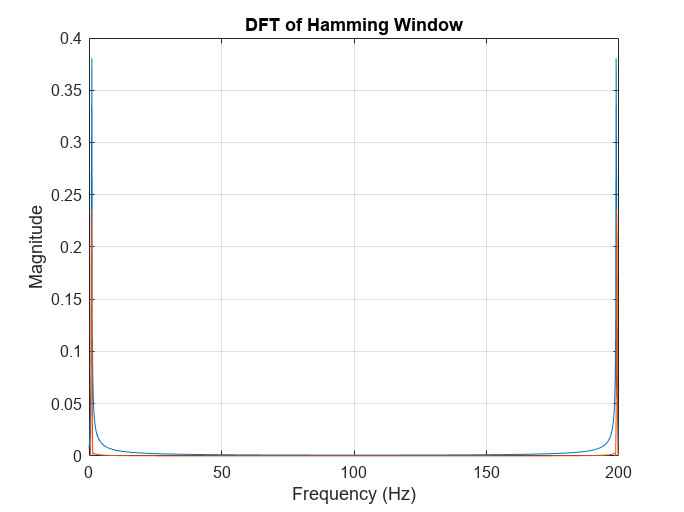

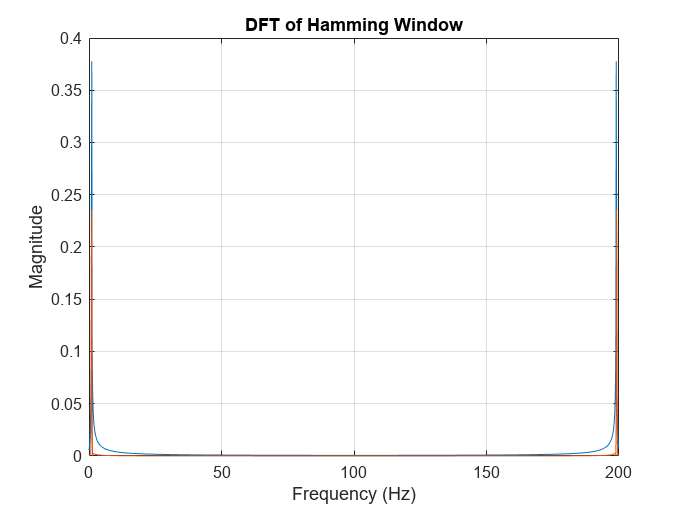

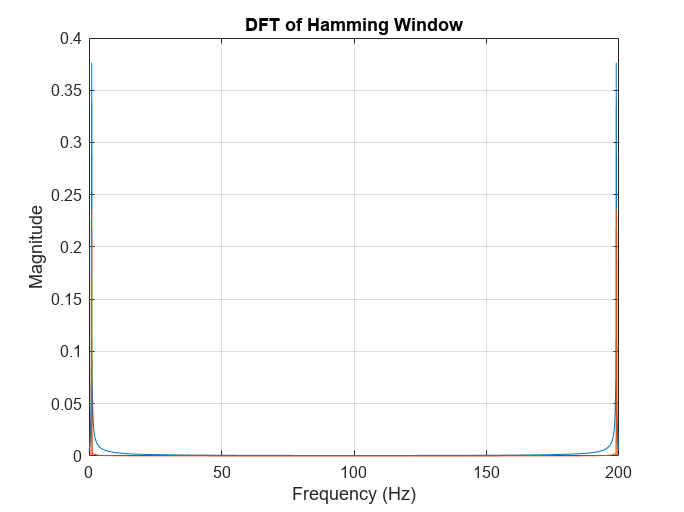




sample_counts = [215, 415, 1115, 1515, 1915];    
for j = 1:length(sample_counts)    
    N = sample_counts(j);
    sample_signal = signal(1:N);   
    dft = abs(fft(sample_signal)/N);
    freq_axis = (0:N-1)*200/N;   
    window = hamming(N);
    windowed_signal = signal(1:N) .* window';
    dft_windowed = abs(fft(windowed_signal))/N;
    freq_axis_windowed = linspace(0, 200, N);
    figure; 
    plot(freq_axis, dft);
    grid on;
    xlabel('Frequency (Hz)');   
    ylabel('Magnitude');
    hold on
    plot(freq_axis_windowed, dft_windowed);    
    title(sprintf('DFT of Hamming Window'));
    xlabel('Frequency (Hz)');    
    ylabel('Magnitude') 
    hold off
end    



% Load the data from the file
data = load('Exp4Data2.txt');

Error using load
Unable to find file or directory 'Exp4Data2.txt'.

fs = 5000; % Assume a sampling frequency of 5000 Hz (adjust if necessary)
N = length(data);

wind = hamming(500);
windowed_signal1 = data .* wind';

% Perform FFT with zero-padding to improve frequency resolution
N_fft = 10000; % Number of points for FFT (zero-padding)
fft_result = abs(fft(windowed_signal1, N_fft))/N_fft;

% Frequency axis in terms of Fs
freq_axis = (0:N_fft-1) / N_fft * fs;

% Plot the magnitude of the FFT result
figure;
subplot(2, 1, 1);
plot(freq_axis, fft_result);
title('Magnitude of FFT (Hamming Window)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Find the frequencies of the two components (peaks)
[~, indices] = findpeaks(abs(fft_result), 'SortStr', 'descend', 'NPeaks', 2);
frequencies_hamming = freq_axis(indices);

fprintf('Frequency components using Hamming window:\n');
fprintf('Frequency 1: %.3f Hz\n', frequencies_hamming(1));
fprintf('Frequency 2: %.3f Hz\n', frequencies_hamming(2));

% Repeat the analysis using a rectangular window
rectangular_window = rectwin(N);
data_rectangular = data .* rectangular_window';

% Perform FFT with zero-padding on the rectangular windowed signal
fft_result_rectangular = abs(fft(data_rectangular, N_fft))/N_fft;

% Plot the magnitude of the FFT result for rectangular window
subplot(2, 1, 2);
plot(freq_axis, abs(fft_result_rectangular));
title('Magnitude of FFT (Rectangular Window)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Find the frequencies of the two components (peaks) for rectangular window
[~, indices_rectangular] = findpeaks(fft_result_rectangular, 'SortStr', 'descend', 'NPeaks', 2);
frequencies_rectangular = freq_axis(indices_rectangular);

fprintf('Frequency components using Rectangular window:\n');
fprintf('Frequency 1: %.3f Hz\n', frequencies_rectangular(1));
fprintf('Frequency 2: %.3f Hz\n', frequencies_rectangular(2));



